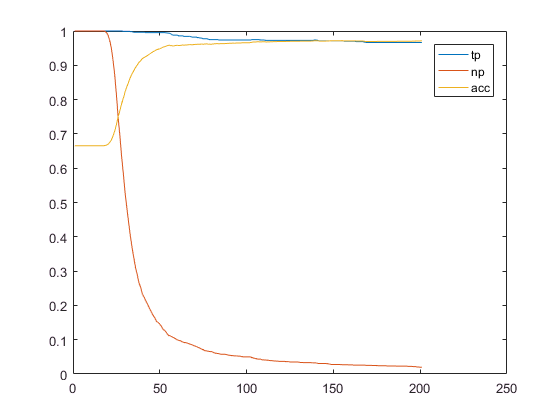


clear;
% trainFolder = 'trainRecord_anti_force/trainRecord_R_4_anti_force';
trainFolder =  'trainRecord_anti_R_5_1';
runDataPreparation;

%%% module structure of a and h?

% case 1: analysis cross multiple epochs
winSize = 50;
nWin = T/winSize;
AmatCellSlidingWin = timeSeries2ACell(a,winSize);

epochEarlystop = 60;

gplus = 1.02;
gminus = 1.0;
omega = 1.0;

modularity = zeros(epochEarlystop,1);
nCommunity = zeros(epochEarlystop,1);
meanCommunitySize = zeros(epochEarlystop,1);
stationarity = zeros(epochEarlystop,1);
S = cell(epochEarlystop,1);
flexibility = zeros(epochEarlystop,1);
allegianceMatrix = zeros(N,N,epochEarlystop);

parfor (i = 1:epochEarlystop,4)
    [modularity(i), nCommunity(i),meanCommunitySize(i),stationarity(i),S{i},flexibility(i)] = multiSliceCommunityStats(AmatCellSlidingWin{i},gplus,gminus,omega);
end

Merging 6000 communities  19           13        4.027
Merging 1784 communities  19           13        7.906
Merging 6000 communities  19           13          3.8
Merging 1776 communities  19           13        8.276
Merging 6000 communities  19           13        3.719
Merging 1742 communities  19           13        8.284
Merging 6000 communities  19           13         4.07
Merging 1722 communities  19           13        8.133
Merging 274 communities  19           13        9.638
Merging 570 communities  19           13        9.406
Merging 529 communities  19           13        9.617
Merging 428 communities  19           13       10.231
Merging 42 communities  19           13        9.683
Merging 16 communities  19           13         9.69
Merging 15 communities  19           13        9.695
Merging 6000 communities  19           13        9.777
Merging 1746 communities  19           13       12.963
Merging 103 communities  19           13        9.636
Merging 36 communitie

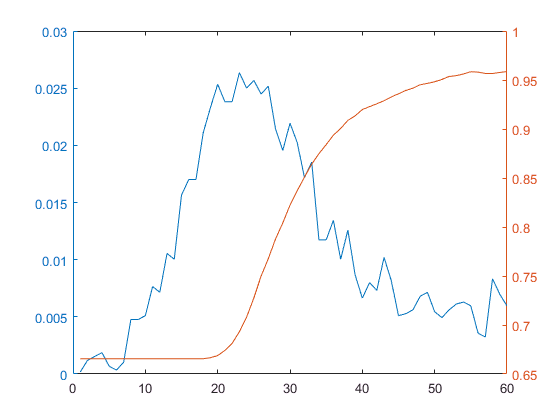

for i = 1:epochEarlystop
    for s = 1:N
        for t = 1:N
            allegianceMatrix(s,t,i) = allegianceMatrix(s,t,i) + nanmean(S{i}(s,:)==S{i}(t,:));
        end
    end
end


% generate robust community structure and calculate the alligence matrix
for i = 1:epochEarlystop
    AmatCellFulSeq{i} = corr(squeeze(a(:,:,i)'));
end

figure;
yyaxis left; plot(flexibility); xlabel('epoch'); ylabel('flexibility');
yyaxis right; plot(acc(1:epochEarlystop)); ylabel('accuracy');

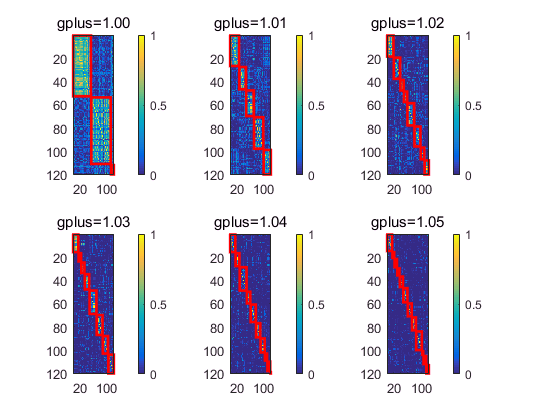

cPartition = {};
allegiance = {};
modularityValue = [];
figure;
for i = 1:6
    gplus = 1.0 + 0.01*(i-1);
    [cPartition{i}, allegiance{i}, modularityValue(i)] = genRobustCommunityFromASeries(AmatCellFulSeq,gplus,1.0);
    subplot(2,3,i);
    plotCommunities(allegiance{i},cPartition{i},2); colorbar;
    title(sprintf('gplus=%.2f',gplus));
end

% calculate the recruitment and integration matrix based on the consensus partition obtained above
for i = 1:6
    nModule = max(cPartition{i});
    riMatrix{i} = zeros(nModule, nModule, epochEarlystop);
    for s = 1:nModule
        for t = 1:nModule 
            riMatrix{i}(s,t,:) = nanmean(nanmean(allegianceMatrix(cPartition{i}==s,cPartition{i}==t,:)));
        end
    end
end

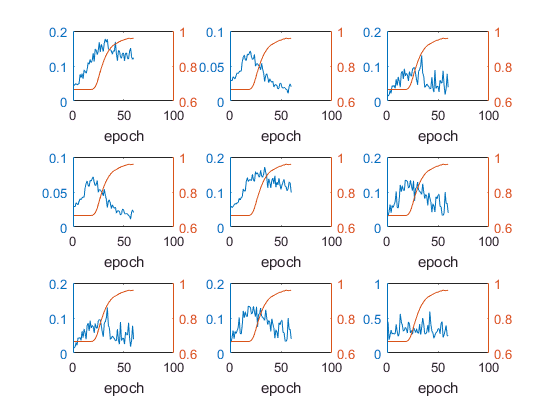

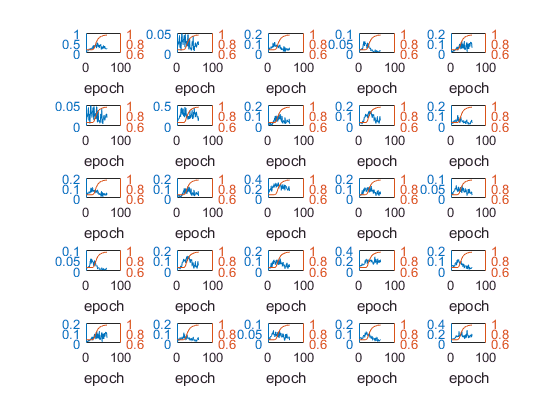

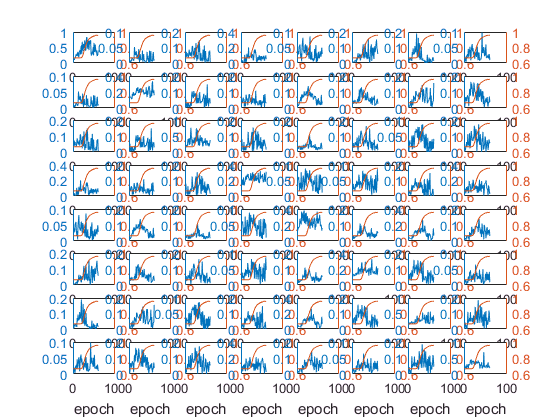

for i = 1:3
    figure;
    count = 0;
    for row = 1: size(riMatrix{i},1)
        for col = 1:size(riMatrix{i},2)
            count = count + 1;
            subplot(size(riMatrix{i},1), size(riMatrix{i},2),count);
            yyaxis left; plot(squeeze(riMatrix{i}(row,col,:))); ylabel('ri-value');
            yyaxis right; plot(acc(1:epochEarlystop)); ylabel('accuracy');
            xlabel('epoch');
        end
    end
end

% case 2: 

% module structure of A?